# The use of $\mathcal{K}$-FCA for the analysis of *C. elegans'* sensorium

 This live script performs a full analysis of chemosensory responses in *C. elegans* using $\mathcal{K}$-FCA . a 5-fold cross-validation strategy. It:

- Preprocesses the original data to compute the peak responses

- Partitions the neuronal response traces into balanced folds for robustness asessment

- Generates concept lattices and visualizes the number of concepts vs. $\varphi$ graph across folds and concentrations

- Smooths the resulting curves to allow for comparison among them and for plotting in the same graph

- Compares different folds using Pearson correlation

- Computes the mean and standard deviation across folds, and identifies regions of minimal variance

- Allows the user to perform the analysis both in min-plus and max-plus semirings and for all 3 concentrations

These analyses are used to assess the robustness and reproducibility of odorant encoding structures across different data splits.

Please cite the corresponding paper when using this script:

DOI: XXXXXXXXX

Author: Emma Reyner-Fuentes; Carmen Peláez-Moreno, Francisco J. Valverde-Albacete

Date: 29/07/2025

## Initialization

%% Main script for Odorants in C. elegans
% Based on the data from:
% "Functional imaging and quantification of multineuronal olfactory responses in C. elegans", 2023.
% https://www.science.org/doi/10.1126/sciadv.ade1249 (accessed Aug. 27, 2023)

clearvars;
close all;

%% Configuration
% Choose semiring: 0 = Min-Plus, 1 = Max-Plus
maxplus = 0;
% Choose concentration: 4 = $10^{-4}$, 5 = $10^{-5}$, 6 = $10^{-6}$
concentration = 4;

NOTE: This script aggregates data from all experiments to build confusion matrices.

## Add required toolboxes to MATLAB path

(Modify these paths according to your local setup)

% Paths of the toolboxes employed
path(matlabpath, '/yourPath/src/phonmat');

path(matlabpath, '/yourPath/src/kfca_matlab/withObjects');
path(matlabpath, '/yourPath/src/Maxminplus_toolbox/withObjects');
path(matlabpath, '/yourPath/src/entropy');
path(matlabpath, '/yourPath/src');

## Define ouput and data directories

labelsdir = '/yourPath/data/input/labelsets/';
input_data = '/yourPath/data/input/Compiled Neural Data/';
out_csvs = sprintf('/yourPath/data/output/csvs/%d/', concentration);
out_tables = '/yourPath/data/output/result_tables/';
out_forcon = '/yourPath/data/output/formal_contexts/';
out_Ks = '/yourPath/data/output/Ks/';
base = '/yourPath/'

base = '/Users/emmareynerfuentes/Desktop/PHD/paper_methods/'

## Load compiled experimental data for the selected concentration

% Load only the selected concentration matrix

datafile = sprintf([input_data, 'compiled_data_conc_%d.mat'], concentration);
load(datafile);

% Select dataset depending on concentration
switch concentration
    case 5
        compiled_LR_ordered = compiled_LR_5_ordered;
        peak_F  = peak_F_5;
        peak_SE = peak_SE_5;
        peak_SD = peak_SD_5;
        Ns      = Ns_5;
    case 6
        compiled_LR_ordered = compiled_LR_6_ordered;
        peak_F  = peak_F_6;
        peak_SE = peak_SE_6;
        peak_SD = peak_SD_6;
        Ns      = Ns_6;
end


## Preprocess the data

Compute mean response around the peak. Neighborhood: 2 seconds before and after the peak (total 4 seconds)

nh = round(2 * compiled_LR_ordered{1}(1).fps);

% For each odorant (23) and neuron pair (11)
for i = 1:23
    for j = 1:11
        % Find the peak (absolute max with sign)
        [~, idx] = max(abs(compiled_LR_ordered{i}(j).mean_trace));
        lidx = max(1, idx - nh);
        hidx = min(idx + nh, 96); % 96 samples per trace

        % Average response around the peak
        peak_F_est(i,j) = mean(compiled_LR_ordered{i}(j).mean_trace(lidx:hidx));
    end
end

% Use the estimated peak responses
od_by_neuron = peak_F_est;

% Save processed data
save(fullfile(out_forcon, sprintf('%d/od_by_neuron.mat', concentration)), 'od_by_neuron');

## $\mathcal{K}$-FCA Analysis - All data 

Average peak responses of 11 chemosensory neurons to 23 odorants, no folds out

ans = '/Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/formal_contexts/4/od_by_neuron.mat'

ans = 47.9708

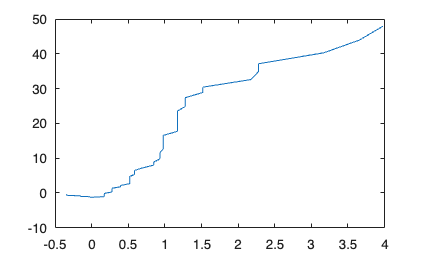

ans =     23    11


Calculando...
Exploring MaxPlus: Varphi: -0.416584. Progress: 0.395257%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_23x11_maxplus/od_by_neuron_23x11_maxplus_structural_-0.41658384654624414090.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.020361 seconds.
Exploring MaxPlus: Varphi: -0.288130. Progress: 6.719368%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_23x11_maxplus/od_by_neuron_23x11_maxplus_structural_-0.28813017774347265965.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.009623 seconds.
Exploring MaxPlus: Varphi: -0.278507. Progress: 7.905138%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_23x11_maxplus/od_by_neuron_23x11_maxplus_structural_-0.27850694100198730707.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapse

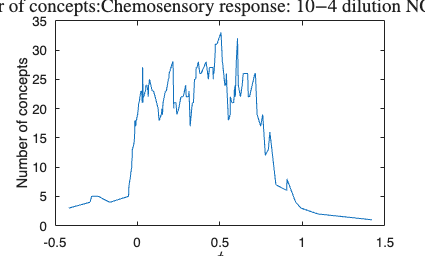

Accuracy: 0.067121


pm = struct with fields:
    mat: [23×11 double]


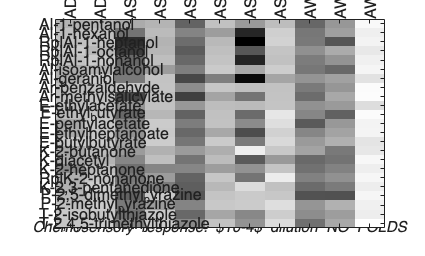


 pm  = 

    title: Chemosensory response: $10{-4}$ dilution NO FOLDS

    Phones involved (emitted): 23, namely  Al-1-pentanol Al-1-hexanol RplAl-1-heptanol RplAl-1-octanol RplAl-1-nonanol Al-isoamylalcohol Al-geraniol Ar-benzaldehyde Ar-methylsalicylate E-ethylacetate E-ethyl_butyrate E-pentylacetate E-ethylheptanoate E-butylbutyrate K-2-butanone K-diacetyl K-2-heptanone RplK-2-nonanone K-2,3-pentanedione P-2,5-dimethyl_pyrazine P-2-methyl_pyrazine T-2-isobutylthiazole T-2,4,5-trimethylthiazole

    Phones involved (received): 11, namely  ADF ADL ASE ASG ASH ASI ASJ ASK AWA AWB AWC


            ADF     ADL     ASE     ASG     ASH     ASI     ASJ     ASK     AWA     AWB     AWC     
    Al-1-pe 0.1362  0.1043  0.1923  0.1278  0.7099  0.0339  0.3105  0.0634  0.6801  0.3332  -0.3686 Al-1-pe 
    Al-1-he 0.0491  0.0389  0.5932  0.0787  0.4729  0.2884  1.1494  -0.0683 0.5635  0.2781  -0.3002 Al-1-he 
    RplAl-1 0.0322  0.0169  1.0954  0.1325  0.6359  0.0925  1.4237  -0.0926 0.5521  0.8

datadir = fullfile(out_forcon, sprintf('%d/', concentration));
matfilename    = 'od_by_neuron';          % Data matrix (rows: odors, columns: neuron pairs)
elabelsfilename = 'labels_celegans_odorants_23';
rlabelsfilename = 'labels_celegans_neuronpairs_11';
ignoreperfect   = 0;
mask            = eye(10); % Example mask

description = sprintf('Chemosensory response: $10{-%d}$ dilution NO FOLDS', concentration);

% Run FCA (Formal Concept Analysis) with Max-Plus/Min-Plus algebra
K = fca.mmp.apps.run_example(datadir, labelsdir, matfilename, ...
    elabelsfilename, rlabelsfilename, out_csvs, maxplus, ...
    ignoreperfect, mask, description);


% Save FCA results
save(fullfile(out_Ks, sprintf('%d/', concentration), matfilename), 'K');

Plot the number of concepts vs. $\varphi$ graph

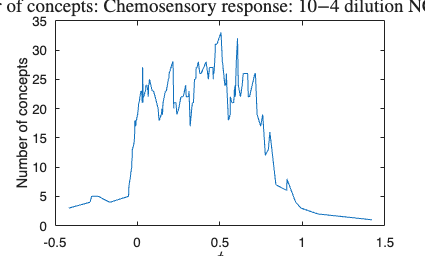

figure;
plot(K.Phis, K.nc);
title(['Number of concepts: ', description], 'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');
xlabel('\phi');
ylabel('Number of concepts');

## Matrix completion to handle NaN values

Use low-rank matrix completion (MC_Nuclear_IALM) as done in the original paper

lambda = 0.1; % Regularization parameter (adjust if needed)

for i = 1:23
    for j = 1:11
        % Extract all trials for a given odorant and neuron pair
        R = compiled_LR_ordered{i}(j).all_traces;

        % Identify NaN positions
        nan_positions = isnan(R);

        % Temporary replace NaNs with column means
        R_temp = R;
        column_means = mean(R_temp, 'omitnan');
        for col = 1:size(R_temp, 2)
            R_temp(nan_positions(:, col), col) = column_means(col);
        end

        % Apply matrix completion algorithm
        [R_completed, ~] = MC_Nuclear_IALM(R_temp, lambda);

        % Replace only original NaN positions with completed values
        R(nan_positions) = R_completed(nan_positions);

        % Update data structure
        compiled_LR_ordered{i}(j).all_traces = R;
    end
end

iteration=10/1000  rankX=0  mu=2.3579e-05
iteration=20/1000  rankX=0  mu=6.1159e-05
iteration=30/1000  rankX=0  mu=0.00015863
iteration=40/1000  rankX=0  mu=0.00041145
iteration=50/1000  rankX=0  mu=0.0010672
iteration=60/1000  rankX=0  mu=0.002768
stopC1=1  stopC2=NaN  stopC3=NaN
iteration=70/1000  rankX=0  mu=0.0071795
stopC1=1  stopC2=NaN  stopC3=NaN
converged
iteration=10/1000  rankX=0  mu=2.3579e-05
iteration=20/1000  rankX=0  mu=6.1159e-05
iteration=30/1000  rankX=0  mu=0.00015863
iteration=40/1000  rankX=0  mu=0.00041145
iteration=50/1000  rankX=0  mu=0.0010672
iteration=60/1000  rankX=0  mu=0.002768
stopC1=1  stopC2=NaN  stopC3=NaN
iteration=70/1000  rankX=1  mu=0.0071795
stopC1=0.84657  stopC2=Inf  stopC3=NaN
converged
iteration=10/1000  rankX=0  mu=2.3579e-05
iteration=20/1000  rankX=0  mu=6.1159e-05
iteration=30/1000  rankX=0  mu=0.00015863
iteration=40/1000  rankX=0  mu=0.00041145
iteration=50/1000  rankX=0  mu=0.0010672
iteration=60/1000  rankX=0  mu=0.002768
stopC1=1  sto

## **K-Fold Cross-Validation for Robustness Testing**

It is not possible to perform LOSO (Leave-One-Subject-Out) because we do not know which traces correspond to each individual animal, and the number of traces varies across neurons.

Approach:

Perform 5-fold cross-validation. For each neuron and odorant:

- Split all traces into 5 equal groups.

- Compute the mean trace per fold.

This ensures that folds are stratified by neuron pair.

n_folds = 5; % Number of folds

% Initialize a data structure for storing fold-specific data
compiled_LR_ordered_fold = cell(1, n_folds);
for k = 1:n_folds
    compiled_LR_ordered_fold{k} = cell(1, 23); % 23 odorants
end

%% Partition data using stratified k-fold (cvpartition)
for i = 1:23  % Iterate over odorants
    all_traces = [];
    neuron_labels = [];

    % Concatenate all traces across neuron pairs to allow stratification
    for j = 1:11
        traces_j = compiled_LR_ordered{i}(j).all_traces;
        all_traces = [all_traces; traces_j];
        neuron_labels = [neuron_labels; j * ones(size(traces_j, 1), 1)];
    end

    % Stratified partitioning based on neuron_labels
    cv = cvpartition(neuron_labels, 'KFold', n_folds);

    % Distribute traces into folds
    for k = 1:n_folds
        fold_indices = cv.test(k);
        fold_all_traces = all_traces(fold_indices, :);
        fold_labels = neuron_labels(fold_indices);

        for j = 1:11
            % Select traces corresponding to neuron pair j for this fold
            neuron_fold_traces = fold_all_traces(fold_labels == j, :);

            if ~isempty(neuron_fold_traces)
                % Compute mean and std ignoring NaN
                fold_mean_trace = mean(neuron_fold_traces, 1, 'omitnan');
                fold_std_trace  = std(neuron_fold_traces, 0, 1, 'omitnan');
                fold_N = sum(~isnan(neuron_fold_traces(:, 1))); % count valid traces

                % Build fold structure
                fold_struct = struct( ...
                    'neuronpair', compiled_LR_ordered{i}(j).neuronpair, ...
                    'fps', compiled_LR_ordered{i}(j).fps, ...
                    'all_traces', neuron_fold_traces, ...
                    'mean_trace', fold_mean_trace, ...
                    'std_trace', fold_std_trace, ...
                    'N', fold_N ...
                );

                % Save structure
                compiled_LR_ordered_fold{k}{i}(j) = fold_struct;
            end
        end
    end
end

%% Compute peak responses using leave-one-fold-out
nh = round(2 * compiled_LR_ordered{1}(1).fps); % +/- 2 seconds around peak
peak_F_est = cell(n_folds, 1);

for fold_out = 1:n_folds
    peak_F_est{fold_out} = zeros(23, 11);

    for i = 1:23       % Odorants
        for j = 1:11   % Neuron pairs
            % Use all folds except fold_out
            folds_to_use = setdiff(1:n_folds, fold_out);

            % Combine mean traces from the selected folds
            combined_traces = [];
            for fold = folds_to_use
                combined_traces = [combined_traces; ...
                    compiled_LR_ordered_fold{fold}{i}(j).mean_trace];
            end

            % Compute combined mean trace
            mean_combined_trace = mean(combined_traces, 1, 'omitnan');

            % Find the index of the absolute peak
            [~, idx] = max(abs(mean_combined_trace), [], 2);

            % Define the neighborhood around the peak
            lidx = max(1, idx - nh);
            hidx = min(idx + nh, size(mean_combined_trace, 2));

            % Compute average value around the peak
            peak_F_est{fold_out}(i, j) = mean(mean_combined_trace(lidx:hidx), 'omitnan');
        end
    end
end

%% Save fold-specific results
od_by_neuron_fold1out = peak_F_est{1};
od_by_neuron_fold2out = peak_F_est{2};
od_by_neuron_fold3out = peak_F_est{3};
od_by_neuron_fold4out = peak_F_est{4};
od_by_neuron_fold5out = peak_F_est{5};

save(fullfile(out_forcon, sprintf('%d/od_by_neuron_fold1out.mat', concentration)), 'od_by_neuron_fold1out');
save(fullfile(out_forcon, sprintf('%d/od_by_neuron_fold2out.mat', concentration)), 'od_by_neuron_fold2out');
save(fullfile(out_forcon, sprintf('%d/od_by_neuron_fold3out.mat', concentration)), 'od_by_neuron_fold3out');
save(fullfile(out_forcon, sprintf('%d/od_by_neuron_fold4out.mat', concentration)), 'od_by_neuron_fold4out');
save(fullfile(out_forcon, sprintf('%d/od_by_neuron_fold5out.mat', concentration)), 'od_by_neuron_fold5out');

## $\mathcal{K}$-FCA Analysis for each fold

Average peak responses of the 11 chemosensory neurons to 23 odorants

ans = '/Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/formal_contexts/4/od_by_neuron_fold1out.mat'

ans = 49.2198

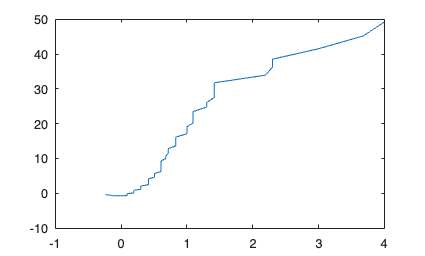

ans =     23    11


Calculando...
Exploring MaxPlus: Varphi: -0.435010. Progress: 0.395257%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold1out_23x11_maxplus/od_by_neuron_fold1out_23x11_maxplus_structural_-0.43500973234310380544.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.020135 seconds.
Exploring MaxPlus: Varphi: -0.273571. Progress: 7.509881%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold1out_23x11_maxplus/od_by_neuron_fold1out_23x11_maxplus_structural_-0.27357135248154895724.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.009059 seconds.
Exploring MaxPlus: Varphi: -0.258119. Progress: 8.300395%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold1out_23x11_maxplus/od_by_neuron_fold1out_23x11_maxplus_structural_-0.25811902113115647861.csv
Please add es.uc3m.kfcatoo

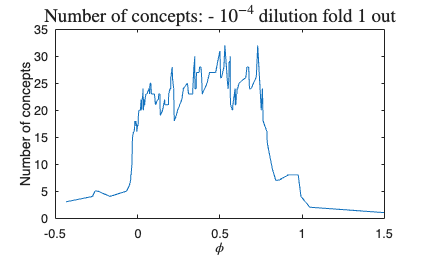

Accuracy: 0.062561


pm = struct with fields:
    mat: [23×11 double]


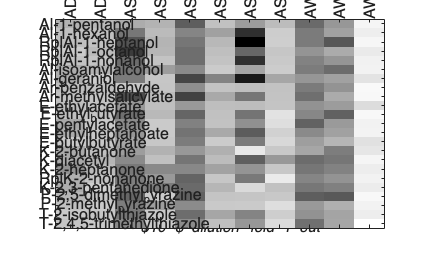


 pm  = 

    title:  - $10^{-4}$ dilution fold 1 out

    Phones involved (emitted): 23, namely  Al-1-pentanol Al-1-hexanol RplAl-1-heptanol RplAl-1-octanol RplAl-1-nonanol Al-isoamylalcohol Al-geraniol Ar-benzaldehyde Ar-methylsalicylate E-ethylacetate E-ethyl_butyrate E-pentylacetate E-ethylheptanoate E-butylbutyrate K-2-butanone K-diacetyl K-2-heptanone RplK-2-nonanone K-2,3-pentanedione P-2,5-dimethyl_pyrazine P-2-methyl_pyrazine T-2-isobutylthiazole T-2,4,5-trimethylthiazole

    Phones involved (received): 11, namely  ADF ADL ASE ASG ASH ASI ASJ ASK AWA AWB AWC


            ADF     ADL     ASE     ASG     ASH     ASI     ASJ     ASK     AWA     AWB     AWC     
    Al-1-pe 0.1520  0.0958  0.1978  0.1393  0.7860  0.0334  0.3149  0.0734  0.6903  0.3566  -0.3524 Al-1-pe 
    Al-1-he 0.0411  0.0397  0.5974  0.0796  0.4870  0.2764  1.1410  -0.0511 0.5636  0.2778  -0.3043 Al-1-he 
    RplAl-1 0.0542  0.0191  0.8579  0.1365  0.6006  0.1026  1.4979  -0.0614 0.5623  0.8403  -0.3597 RplA

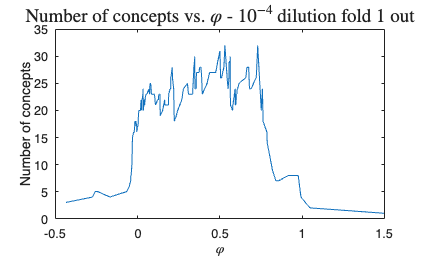

ans = '/Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/formal_contexts/4/od_by_neuron_fold2out.mat'

ans = 50.6258

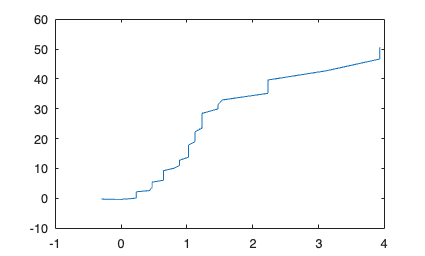

ans =     23    11


Calculando...
Exploring MaxPlus: Varphi: -0.413220. Progress: 0.395257%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold2out_23x11_maxplus/od_by_neuron_fold2out_23x11_maxplus_structural_-0.41322007413418032629.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.004784 seconds.
Exploring MaxPlus: Varphi: -0.305677. Progress: 5.138340%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold2out_23x11_maxplus/od_by_neuron_fold2out_23x11_maxplus_structural_-0.30567696845806674455.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.005705 seconds.
Exploring MaxPlus: Varphi: -0.281422. Progress: 7.114625%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold2out_23x11_maxplus/od_by_neuron_fold2out_23x11_maxplus_structural_-0.28142196636800859144.csv
Please add es.uc3m.kfcatoo

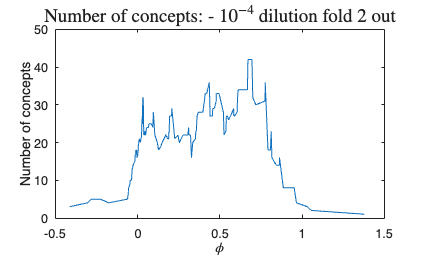

Accuracy: 0.065847


pm = struct with fields:
    mat: [23×11 double]


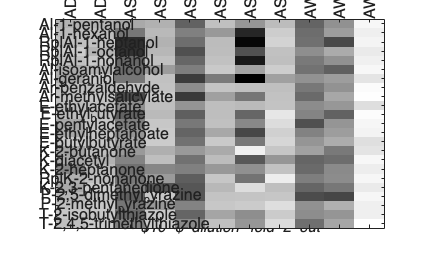


 pm  = 

    title:  - $10^{-4}$ dilution fold 2 out

    Phones involved (emitted): 23, namely  Al-1-pentanol Al-1-hexanol RplAl-1-heptanol RplAl-1-octanol RplAl-1-nonanol Al-isoamylalcohol Al-geraniol Ar-benzaldehyde Ar-methylsalicylate E-ethylacetate E-ethyl_butyrate E-pentylacetate E-ethylheptanoate E-butylbutyrate K-2-butanone K-diacetyl K-2-heptanone RplK-2-nonanone K-2,3-pentanedione P-2,5-dimethyl_pyrazine P-2-methyl_pyrazine T-2-isobutylthiazole T-2,4,5-trimethylthiazole

    Phones involved (received): 11, namely  ADF ADL ASE ASG ASH ASI ASJ ASK AWA AWB AWC


            ADF     ADL     ASE     ASG     ASH     ASI     ASJ     ASK     AWA     AWB     AWC     
    Al-1-pe 0.1222  0.1086  0.1924  0.1346  0.6878  0.0334  0.3220  0.0576  0.6718  0.3571  -0.3516 Al-1-pe 
    Al-1-he 0.0581  0.0422  0.5400  0.0772  0.4787  0.3054  1.1059  -0.0619 0.6108  0.2773  -0.2970 Al-1-he 
    RplAl-1 0.0299  0.0206  1.0564  0.1277  0.6050  0.0564  1.3270  -0.0987 0.5881  0.8623  -0.3312 RplA

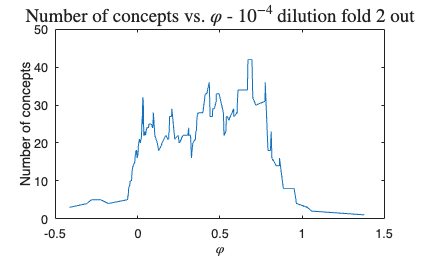

ans = '/Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/formal_contexts/4/od_by_neuron_fold3out.mat'

ans = 43.8074

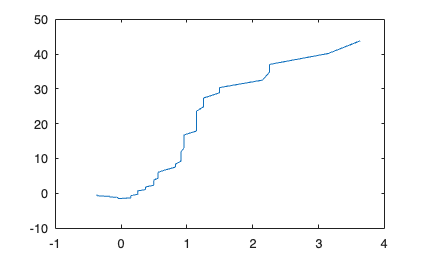

ans =     23    11


Calculando...
Exploring MaxPlus: Varphi: -0.419212. Progress: 0.395257%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold3out_23x11_maxplus/od_by_neuron_fold3out_23x11_maxplus_structural_-0.41921223229374260377.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.011030 seconds.
Exploring MaxPlus: Varphi: -0.288554. Progress: 7.114625%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold3out_23x11_maxplus/od_by_neuron_fold3out_23x11_maxplus_structural_-0.28855376880856559163.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.009376 seconds.
Exploring MaxPlus: Varphi: -0.282657. Progress: 7.509881%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold3out_23x11_maxplus/od_by_neuron_fold3out_23x11_maxplus_structural_-0.28265713422111865549.csv
Please add es.uc3m.kfcatoo

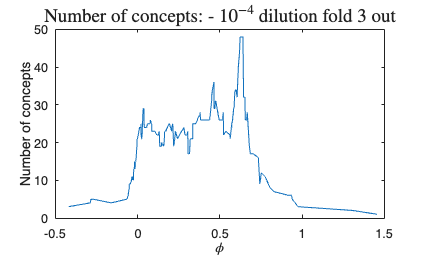

Accuracy: 0.069592


pm = struct with fields:
    mat: [23×11 double]


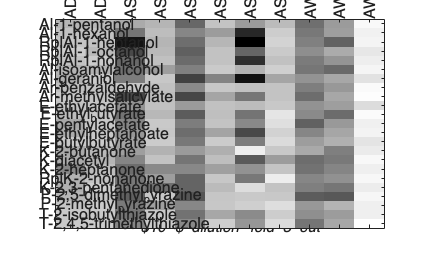


 pm  = 

    title:  - $10^{-4}$ dilution fold 3 out

    Phones involved (emitted): 23, namely  Al-1-pentanol Al-1-hexanol RplAl-1-heptanol RplAl-1-octanol RplAl-1-nonanol Al-isoamylalcohol Al-geraniol Ar-benzaldehyde Ar-methylsalicylate E-ethylacetate E-ethyl_butyrate E-pentylacetate E-ethylheptanoate E-butylbutyrate K-2-butanone K-diacetyl K-2-heptanone RplK-2-nonanone K-2,3-pentanedione P-2,5-dimethyl_pyrazine P-2-methyl_pyrazine T-2-isobutylthiazole T-2,4,5-trimethylthiazole

    Phones involved (received): 11, namely  ADF ADL ASE ASG ASH ASI ASJ ASK AWA AWB AWC


            ADF     ADL     ASE     ASG     ASH     ASI     ASJ     ASK     AWA     AWB     AWC     
    Al-1-pe 0.1289  0.1002  0.2082  0.1255  0.6936  0.0273  0.3135  0.0854  0.6405  0.3197  -0.3701 Al-1-pe 
    Al-1-he 0.0359  0.0223  0.5934  0.0675  0.4724  0.3079  1.1673  -0.0520 0.5731  0.2920  -0.3167 Al-1-he 
    RplAl-1 0.0082  0.0207  1.3068  0.1261  0.6462  0.1201  1.4550  -0.0961 0.5169  0.7341  -0.3378 RplA

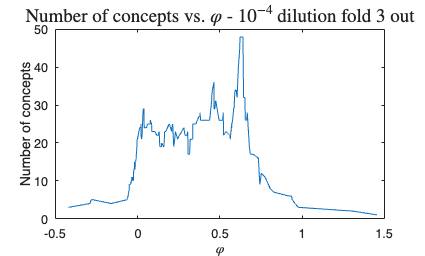

ans = '/Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/formal_contexts/4/od_by_neuron_fold4out.mat'

ans = 52.7604

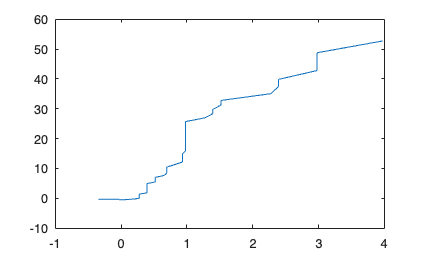

ans =     23    11


Calculando...
Exploring MaxPlus: Varphi: -0.407545. Progress: 0.395257%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold4out_23x11_maxplus/od_by_neuron_fold4out_23x11_maxplus_structural_-0.40754496189106759196.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.005523 seconds.
Exploring MaxPlus: Varphi: -0.284251. Progress: 6.324111%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold4out_23x11_maxplus/od_by_neuron_fold4out_23x11_maxplus_structural_-0.28425053835343666586.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.007317 seconds.
Exploring MaxPlus: Varphi: -0.278192. Progress: 7.509881%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold4out_23x11_maxplus/od_by_neuron_fold4out_23x11_maxplus_structural_-0.27819154025997644419.csv
Please add es.uc3m.kfcatoo

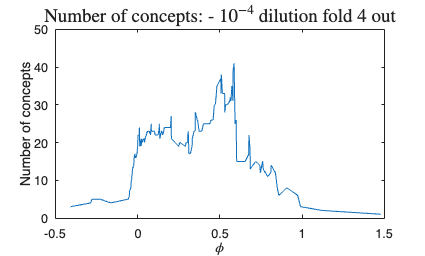

Accuracy: 0.065276


pm = struct with fields:
    mat: [23×11 double]


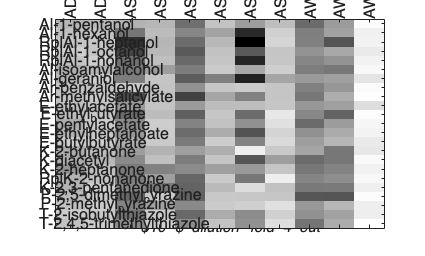


 pm  = 

    title:  - $10^{-4}$ dilution fold 4 out

    Phones involved (emitted): 23, namely  Al-1-pentanol Al-1-hexanol RplAl-1-heptanol RplAl-1-octanol RplAl-1-nonanol Al-isoamylalcohol Al-geraniol Ar-benzaldehyde Ar-methylsalicylate E-ethylacetate E-ethyl_butyrate E-pentylacetate E-ethylheptanoate E-butylbutyrate K-2-butanone K-diacetyl K-2-heptanone RplK-2-nonanone K-2,3-pentanedione P-2,5-dimethyl_pyrazine P-2-methyl_pyrazine T-2-isobutylthiazole T-2,4,5-trimethylthiazole

    Phones involved (received): 11, namely  ADF ADL ASE ASG ASH ASI ASJ ASK AWA AWB AWC


            ADF     ADL     ASE     ASG     ASH     ASI     ASJ     ASK     AWA     AWB     AWC     
    Al-1-pe 0.1423  0.1046  0.1595  0.1309  0.6533  0.0406  0.3206  0.0712  0.6822  0.3328  -0.3838 Al-1-pe 
    Al-1-he 0.0621  0.0271  0.6036  0.0899  0.4826  0.2752  1.1740  -0.0563 0.5352  0.2917  -0.2960 Al-1-he 
    RplAl-1 0.0223  0.0106  1.1219  0.1306  0.6775  0.1171  1.4774  -0.0941 0.5293  0.8586  -0.3065 RplA

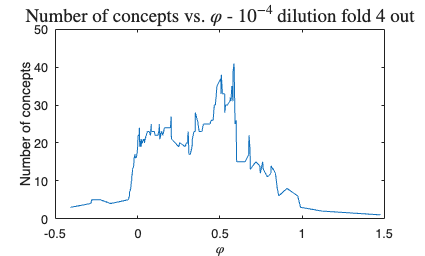

ans = '/Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/formal_contexts/4/od_by_neuron_fold5out.mat'

ans = 44.4652

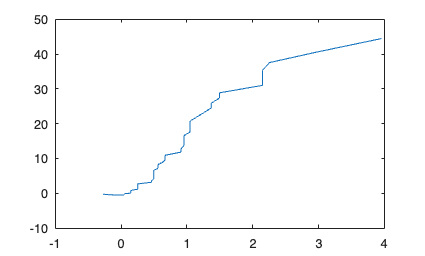

ans =     23    11


Calculando...
Exploring MaxPlus: Varphi: -0.417427. Progress: 0.395257%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold5out_23x11_maxplus/od_by_neuron_fold5out_23x11_maxplus_structural_-0.41742673519100498281.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.007629 seconds.
Exploring MaxPlus: Varphi: -0.276462. Progress: 7.509881%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold5out_23x11_maxplus/od_by_neuron_fold5out_23x11_maxplus_structural_-0.27646230070415972468.csv
Please add es.uc3m.kfcatools.Concepts to your classpath: javaaddpath path
Elapsed time is 0.007684 seconds.
Exploring MaxPlus: Varphi: -0.269520. Progress: 7.905138%
Writing: /Users/emmareynerfuentes/Desktop/PHD/paper_methods/data/output/csvs/4/od_by_neuron_fold5out_23x11_maxplus/od_by_neuron_fold5out_23x11_maxplus_structural_-0.26951959566150712755.csv
Please add es.uc3m.kfcatoo

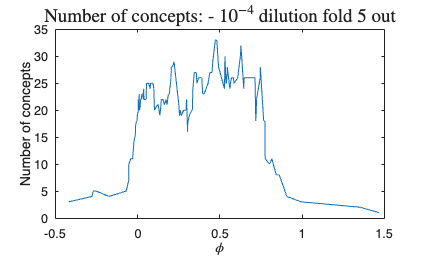

Accuracy: 0.072963


pm = struct with fields:
    mat: [23×11 double]


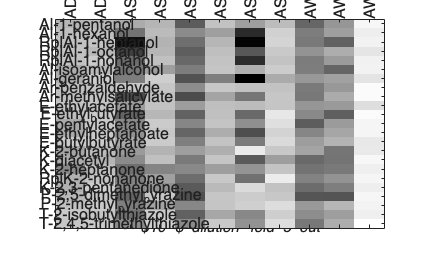


 pm  = 

    title:  - $10^{-4}$ dilution fold 5 out

    Phones involved (emitted): 23, namely  Al-1-pentanol Al-1-hexanol RplAl-1-heptanol RplAl-1-octanol RplAl-1-nonanol Al-isoamylalcohol Al-geraniol Ar-benzaldehyde Ar-methylsalicylate E-ethylacetate E-ethyl_butyrate E-pentylacetate E-ethylheptanoate E-butylbutyrate K-2-butanone K-diacetyl K-2-heptanone RplK-2-nonanone K-2,3-pentanedione P-2,5-dimethyl_pyrazine P-2-methyl_pyrazine T-2-isobutylthiazole T-2,4,5-trimethylthiazole

    Phones involved (received): 11, namely  ADF ADL ASE ASG ASH ASI ASJ ASK AWA AWB AWC


            ADF     ADL     ASE     ASG     ASH     ASI     ASJ     ASK     AWA     AWB     AWC     
    Al-1-pe 0.1317  0.0918  0.2035  0.1316  0.7863  0.0322  0.2951  0.0773  0.7140  0.3568  -0.3571 Al-1-pe 
    Al-1-he 0.0540  0.0457  0.6249  0.0849  0.4393  0.2964  1.1543  -0.0757 0.5451  0.2935  -0.2885 Al-1-he 
    RplAl-1 0.0374  0.0099  1.3520  0.1440  0.6474  0.1254  1.4310  -0.0963 0.5744  0.7461  -0.3158 RplA

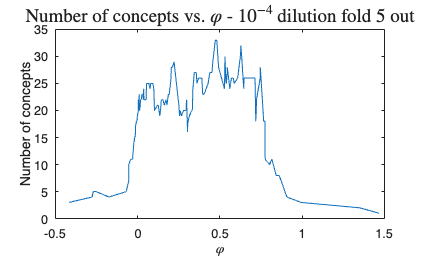

% Preallocate K_results as a cell array with n_folds elements
K_results = cell(1, n_folds);

for fold_idx = 1:n_folds
    datadir = fullfile(out_forcon, sprintf('%d/', concentration));
    matfilename = sprintf('od_by_neuron_fold%dout', fold_idx);
    elabelsfilename = 'labels_celegans_odorants_23';
    rlabelsfilename = 'labels_celegans_neuronpairs_11';
    ignoreperfect = 0;
    mask = eye(10);
    description = sprintf(' - $10^{-%d}$ dilution fold %d out', ...
        concentration, fold_idx);

    K_fold = fca.mmp.apps.run_example(datadir, labelsdir, matfilename, ...
        elabelsfilename, rlabelsfilename, out_csvs, maxplus, ...
        ignoreperfect, mask, description);

    save(fullfile(out_Ks, sprintf('%d/', concentration), matfilename), 'K_fold');

    % Plot results for this fold
    figure;
    plot(K_fold.Phis, K_fold.nc);
    title(['Number of concepts vs. $\varphi$', description], 'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');
    xlabel('$\varphi$', 'Interpreter', 'latex');
    ylabel('Number of concepts');

    % Store K results dynamically

    K_results{fold_idx} = K_fold;
end


K1 = K_results{1};
K2 = K_results{2};
K3 = K_results{3};
K4 = K_results{4};
K5 = K_results{5};


Plot all folds together

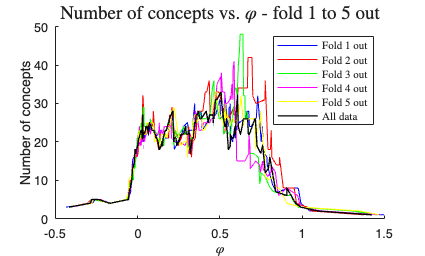

description = '- fold 1 to 5 out';
figure;
colors = {'b','r','g','m','y'};
line_width = 0.5; % Base line width for folds

hold on;
for fold_idx = 1:n_folds
    plot(K_results{fold_idx}.Phis, K_results{fold_idx}.nc, ...
         'Color', colors{fold_idx}, 'LineWidth', line_width);
end

% Plot the "all data" result in black and 0.5 thicker than the others
plot(K.Phis, K.nc, 'k', 'LineWidth', line_width + 0.5);

title(['Number of concepts vs. $\varphi$ ', description], ...
      'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');
xlabel('$\varphi$', 'Interpreter', 'latex');
ylabel('Number of concepts');
legend('Fold 1 out','Fold 2 out','Fold 3 out','Fold 4 out','Fold 5 out','All data', ...
       'Interpreter','latex');
hold off;

## Smooth curves and unify the number of phi values across folds

Step: $10^{-4}$, unify the number of $\varphi$s in all vectors to be able to graph and compare them together. 

% Collect all phi values across folds and determine the global range
all_phis = [K1.Phis, K2.Phis, K3.Phis, K4.Phis, K5.Phis];
phi_min = min(all_phis);
phi_max = max(all_phis);

% Create a uniform phi grid with step 0.001
uniform_phis = phi_min:0.001:phi_max;

% Select correct interpolation function depending on maxplus
if maxplus == 1
    interp_fun = @fill_nc_for_uniform_phis_maxplus;
else
    interp_fun = @fill_nc_for_uniform_phis;
end

% Interpolate nc values for all folds to a uniform phi grid
K1_nc_uniform = interp_fun(K1.Phis, K1.nc, uniform_phis);
K2_nc_uniform = interp_fun(K2.Phis, K2.nc, uniform_phis);
K3_nc_uniform = interp_fun(K3.Phis, K3.nc, uniform_phis);
K4_nc_uniform = interp_fun(K4.Phis, K4.nc, uniform_phis);
K5_nc_uniform = interp_fun(K5.Phis, K5.nc, uniform_phis);
K_nc_uniform  = interp_fun(K.Phis,  K.nc,  uniform_phis);

% Store uniform phi grid for all folds
K1_Phis_uniform = uniform_phis;

## Compute Pearson correlation between context matrices

% Matrices of average peak responses: 5 folds + all data
od_matrices = {od_by_neuron_fold1out, od_by_neuron_fold2out, ...
               od_by_neuron_fold3out, od_by_neuron_fold4out, ...
               od_by_neuron_fold5out, od_by_neuron};

n = length(od_matrices);
R = zeros(n); % Pearson correlation matrix

% Compute pairwise Pearson correlations between vectorized matrices
for i = 1:n
    for j = i+1:n
        vec_i = od_matrices{i}(:);
        vec_j = od_matrices{j}(:);
        R(i, j) = corr(vec_i, vec_j, 'type', 'Pearson');
        R(j, i) = R(i, j);
    end
end

% Set diagonal to 1
R(logical(eye(n))) = 1;

disp('Pearson correlation matrix:');

Pearson correlation matrix:


disp(R);

    1.0000    0.9941    0.9926    0.9940    0.9906    0.9970
    0.9941    1.0000    0.9937    0.9943    0.9912    0.9971
    0.9926    0.9937    1.0000    0.9939    0.9939    0.9967
    0.9940    0.9943    0.9939    1.0000    0.9936    0.9973
    0.9906    0.9912    0.9939    0.9936    1.0000    0.9965
    0.9970    0.9971    0.9967    0.9973    0.9965    1.0000



## Mean and standard deviation across folds (number of concept curves)

% Combine nc values from all folds
all_nc = [K1_nc_uniform; K2_nc_uniform; K3_nc_uniform; K4_nc_uniform; K5_nc_uniform];

% Compute mean and std across folds for each phi
mean_nc = mean(all_nc, 1, 'omitnan');
std_nc  = std(all_nc, 0, 1, 'omitnan');

% Define upper and lower bounds for shaded area
upper_bound = mean_nc + std_nc;
lower_bound = mean_nc - std_nc;

assert(length(K1_Phis_uniform) == length(upper_bound), ...
    'Mismatch between phi vector and bounds length.');

Plot Number of Concept vs $\varphi$ graph comparison - Mean all folds out vs. all data

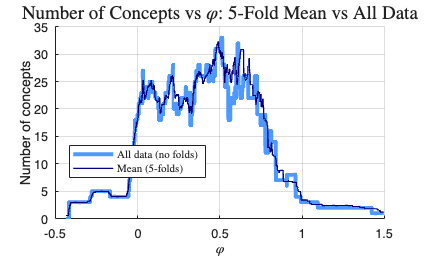

figure;
hold on;

color_all_data = [0.3 0.6 1]; % Light blue
color_mean = [0 0 0.5];       % Navy

% Plot all-data curve (no folds)
plot(K1_Phis_uniform, K_nc_uniform, '-', 'Color', color_all_data, ...
    'LineWidth', 3, 'DisplayName', 'All data (no folds)');

% Plot mean from folds
plot(K1_Phis_uniform, mean_nc, '-', 'Color', color_mean, ...
    'LineWidth', 1, 'DisplayName', 'Mean (5-folds)');

% Labels and legend
title('Number of Concepts vs $\varphi$: 5-Fold Mean vs All Data', ...
    'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');
xlabel('$\varphi$', 'Interpreter', 'latex');
ylabel('Number of concepts');
legend('show', 'Location', 'best', 'Interpreter', 'latex');

grid on;
hold off;

## Find phi points with minimum variance (std)

% For maxplus we consider phi<0, for minplus phi>0
if maxplus == 0
    indices = find(K1_Phis_uniform > 0);
else
    indices = find(K1_Phis_uniform < 0);
end

positive_std_nc  = std_nc(indices);
positive_phis    = K1_Phis_uniform(indices);
positive_mean_nc = mean_nc(indices);

% Local minima of std (using negative to detect minima)
[~, min_indices] = findpeaks(-positive_std_nc);
min_values = positive_std_nc(min_indices);
min_phis   = positive_phis(min_indices);

% Sort minima by std value
[sorted_min_values, sort_idx] = sort(min_values);
sorted_min_phis    = min_phis(sort_idx);
sorted_min_indices = min_indices(sort_idx);

% Select all minima (no filtering)
selected_min_phis  = sorted_min_phis;
selected_min_values = sorted_min_values;
selected_indices    = sorted_min_indices;

% Mean values at minima
top_10_min_mean_values = positive_mean_nc(selected_indices);


## Plot mean curve with std and mark minima

figure;
description = 'Chemosensory response: mean with STD and local minima';

% Shaded region for mean ± std
fill_x = [K1_Phis_uniform, fliplr(K1_Phis_uniform)];
fill_y = [upper_bound, fliplr(lower_bound)];
fill(fill_x, fill_y, [0.3010 0.7450 0.9330], ...
     'EdgeColor', 'none', 'FaceAlpha', 0.1); 
hold on;

% Plot mean curve and std
plot(K1_Phis_uniform, mean_nc, 'k', 'LineWidth', 2);
plot(K1_Phis_uniform, std_nc, 'r');

% Mark minima points
scatter(selected_min_phis, top_10_min_mean_values, ...
        10, 'r', 'filled');

title(['Number of concepts: ', description],'FontSize',14, ...
      'FontWeight','bold', 'Interpreter','latex');
xlabel('\phi');
ylabel('Number of concepts');
legend('Mean ± STD','Mean (all folds)','STD','Local minima', ...
       'Interpreter', 'latex');

% Print results
for i = 1:length(selected_min_phis)
    fprintf('Phi: %.3f, STD: %.4f\n', ...
        selected_min_phis(i), selected_min_values(i));
end

Phi: -0.407, STD: 0.0000
Phi: -0.258, STD: 0.0000
Phi: -0.160, STD: 0.0000
Phi: -0.056, STD: 0.5477
Phi: -0.036, STD: 0.7071
Phi: -0.033, STD: 0.8367
Phi: -0.014, STD: 0.8367
Phi: -0.007, STD: 0.8367
Phi: -0.018, STD: 1.0000
Phi: -0.022, STD: 1.0954
Phi: -0.027, STD: 1.4832
Phi: -0.048, STD: 1.5811


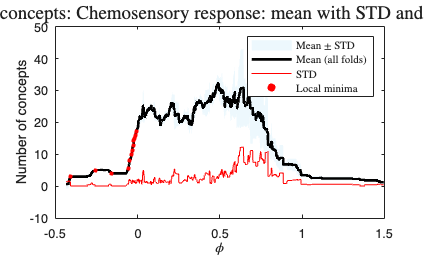

hold off;

## Save results table

result_table = table(K1_nc_uniform, K2_nc_uniform, K3_nc_uniform, K4_nc_uniform, K5_nc_uniform, K_nc_uniform, K1_Phis_uniform, ...
    mean_nc, std_nc, upper_bound, lower_bound, ...
    selected_min_phis, selected_min_values, selected_indices, ...
    'VariableNames', {'K1_nc_uniform', 'K2_nc_uniform', 'K3_nc_uniform', 'K4_nc_uniform', 'K5_nc_uniform', 'K_nc_uniform', 'K1_Phis_uniform', ...
    'mean_nc', 'std_nc', 'upper_bound', 'lower_bound', ...
    'selected_phis', 'selected_std', 'selected_indices'});

if maxplus == 1
    save(fullfile(out_tables, sprintf('result_table_conc%d_maxplus.mat', concentration)), 'result_table');
else
    save(fullfile(out_tables, sprintf('result_table_conc%d.mat', concentration)), 'result_table');
end
